usage: teamwork for week 5

author: 黄哲昊 毛晨光 鲁潇阳

date: 2020.4.4

clear all; close all; clc

**1.  证明方程 **$$e^x+10x-2=0$$**存在唯一实根， 用二分法求此根， 要求误差不超过**$ $\frac{1}{2}\times 10^{-2}$$**  。**

解：

设$f(x) =e^x + 10x - 2$，使用matlab符号运算求导：

syms x
f_1(x) = exp(x) + 10*x - 2

$$f\_1(x) = 10\,x+{\mathrm{e}}^{x}-2$$

df(x) = diff(f_1(x))% the first-order derivative of f(x)

$$df(x) = {\mathrm{e}}^{x}+10$$

f_1 = @(x)(exp(x) + 10*x - 2)

f_1 = 包含以下值的 function_handle :
    @(x)(exp(x)+10*x-2)


greater_than_0 = f_1(1)% f(1) greater than 0

greater_than_0 =   10.718281828459045


less_than_0 = f_1(0)% f(0) less than 0

less_than_0 =     -1


得到$\frac{df(x)}{dx} = e^x+10$，易得$(\forall x)(\frac{df(x)}{dx}>0)$，即$f(x)$在整个实数上单调增，且$f(x)$在整个实数上连续，且由于$f(1)>0,f(0)<0$，满足零点存在定理，故函数$f(x)$存在唯一零点，即方程$$e^x+10x-2=0$$存在唯一实根。

[x_1, ~] = dichotomy(f_1, 1, 0, 0.5e-2)

dichotomy:
the root of f(x)=0 is x = 0.089844, the number of iterations is 7

x_1 =    0.089843750000000


由二分法得到近似解$x\approx 0.0898$。

**2. 用定点迭代法求解方程**$$x=e^{-x}$$**在**$$x=0.5$$**附近的一个根， 要求：事先确定有根区间并判断迭代公式的收敛性， 误差上限为**$$\epsilon=10^{-5}$$**.**

解：

sample = 0:0.01:1

sample =                    0   0.010000000000000   0.020000000000000   0.030000000000000   0.040000000000000   0.050000000000000   0.060000000000000   0.070000000000000   0.080000000000000   0.090000000000000   0.100000000000000   0.110000000000000   0.120000000000000   0.130000000000000   0.140000000000000   0.150000000000000   0.160000000000000   0.170000000000000   0.180000000000000   0.190000000000000   0.200000000000000   0.210000000000000   0.220000000000000   0.230000000000000   0.240000000000000   0.250000000000000   0.260000000000000   0.270000000000000   0.280000000000000   0.290000000000000   0.300000000000000   0.310000000000000   0.320000000000000   0.330000000000000   0.340000000000000   0.350000000000000   0.360000000000000   0.370000000000000   0.380000000000000   0.390000000000000   0.400000000000000   0.410000000000000   0.420000000000000   0.430000000000000   0.440000000000000   0.450000000000000   0.460000000000000   0.470000000000000   0.480000000000000   0.490000

f_2_1 = @(x)x

f_2_1 = 包含以下值的 function_handle :
    @(x)x


f_2_2 = @(x)(exp(-x))

f_2_2 = 包含以下值的 function_handle :
    @(x)(exp(-x))


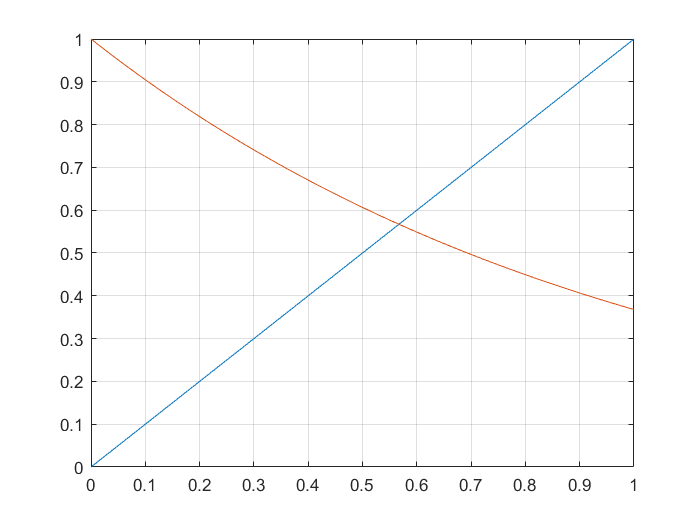

plot(sample, f_2_1(sample), sample, f_2_2(sample))
grid on

设$g(x) =e^{-x}$，求导得到$|g'(x)|=|-e^{-x}|=e^{-x}$，易得当$x>0$时，满足$|g'(x)|<1$，从图中容易看出，根在$(0,1)$的区间内，且满足定点迭代公式的收敛性，故取$$x=0.5$$为初始迭代点$x_0$。

format long
[x_2, ~] = fixedPoint(f_2_2, 0.5, 1e-5, 100000)

fixedPoint:
the root of g(x)=x is x = 0.567148, the number of iterations is 17

x_2 =    0.567147746330625


由定点迭代法得到近似解$x\approx 0.56714$。

**3. 用定点迭代法和定点迭代法的Aitken(埃特金)加速方法， 计算**$$x=\ln (x+2)$$**在**$$x=0.5$$**附近的近似根， 要求**$$\vert x^*-x_k\vert<10^{-4}$$**, 并比较收敛的快慢。**

解：

f_3 = @(x)log(x+2)

f_3 = 包含以下值的 function_handle :
    @(x)log(x+2)


[x_3_1, flag_3_1] = fixedPoint(f_3, 0.5, 1e-4, 10000)

fixedPoint:
the root of g(x)=x is x = 1.146114, the number of iterations is 8

x_3_1 =    1.146113571453652


flag_3_1 =      8


[x_3_2, flag_3_2] = fixedPointWithAitken(f_3, 0.5, 1e-4, 10000)

fixedPoint with Aitken:
the root of g(x)=x is x = 1.146198, the number of iterations is 6

x_3_2 =    1.146198178947666


flag_3_2 =      6


用定点迭代法和Aitken加速方法都得到近似解$x\approx 1.1461$，定点迭代法经过8次迭代得到结果，而Aitken加速方法仅经过6次迭代就得到了结果，Aitken加速方法收敛速度比普通的定点迭代法更快。

**4. 割线法是跟牛顿法相似的数值方法， 但它需要两个接近真实根的初值**$$x_0$$**和**$$x_1$$**，由此得到函数**$$f(x)$$**上两个点**$$(x_0,y_0=f(x_0))$$**和**$$(x_1,y_1=f(x_1))$$**，连接这两点得到一条直线, 称之为割线:**

   
$$$$
    y-y_1=\frac{y_1-y_0}{x_1-x_0}(x-x_1)
    $$$$


**    我们用这条割线近似函数本身， 因此设**$$y=0$$**，由上式解出割线与**$$x$$**-轴的截点，作为下次迭代的初值。这个过程一直进行下去，利用如下迭代关系：**

   
$$ $$
    x_{n+1}=x_n-\frac{x_n-x_{n-1}}{y_n-y_{n-1}}y_n
    $$$$


**    分别用割线法和牛顿法求解下列方程的根， 比较两者的收敛速度：**

**(1)  **$ $xe^x-1=0$$**;**

**(2)   **$$\ln x+x-2=0$$**.**

解：

(1)设$f_1(x)=xe^x-1$，易得$f'_1(x)=e^x+xe^x$

f_4_1 = @(x)(x.*exp(x) - 1)

f_4_1 = 包含以下值的 function_handle :
    @(x)(x.*exp(x)-1)


df_4_1 = @(x)(exp(x) + x.*exp(x))

df_4_1 = 包含以下值的 function_handle :
    @(x)(exp(x)+x.*exp(x))


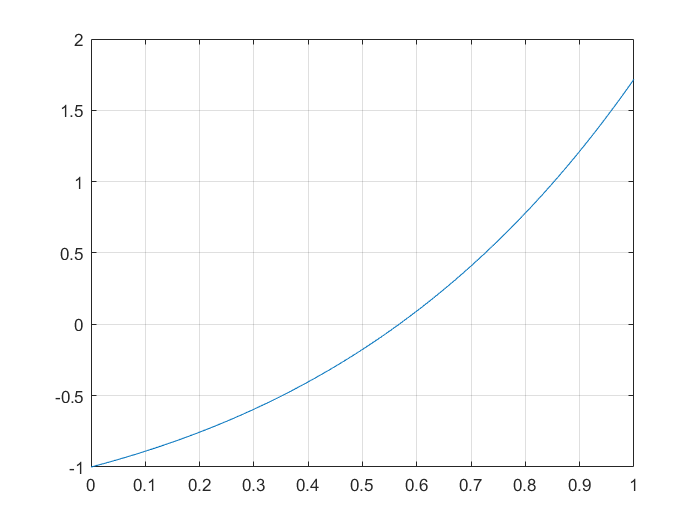

sample1 = 0:0.01:1;
plot(sample1, f_4_1(sample1))
grid on

由图解法可以得到根在区间$(0,1)$内，取$0.5$为牛顿-拉夫森方法的初始估计值，$x_0=0.5,x_1=0.6$为割线法的两个初值。

**************************************************************************************************************

***我们组写了两种牛顿-拉夫森方法，区别在于一种需要将导数作为参数传入，另一种在函数内部计算导数，前者考虑到存在函数无法使用matlabFunction函数转换为可计算函数，故给出参数传入接口；后者对于一些复杂函数方便了牛顿法的使用。***

***在之后的Halley函数同理，我们也分为了需要提供导数和内置导数计算两个版本。***

**************************************************************************************************************

[x_4_1_Netwon, flag_4_1_Netwon] = Netwon(f_4_1, df_4_1, 0.5, 1e-5, 10000, 1, 0)

Newton's method:
the root of f(x)=0 is x = 0.567143, the number of iterations is 4

x_4_1_Netwon =    0.567143290409784


flag_4_1_Netwon =      4


[x_4_1_Netwon_without_df, flag_4_1_Netwon_without_df] = Netwon_without_df(f_4_1, 0.5, 1e-5, 10000, 1, 0)

Newton's method without df:
the root of f(x)=0 is x = 0.567143, the number of iterations is 4

x_4_1_Netwon_without_df =    0.567143290409784


flag_4_1_Netwon_without_df =      4


[x_4_1_secant, flag_4_1_secant] = secant(f_4_1, 0.5, 0.6, 1e-5, 10000)

secant method:
the root of f(x)=0 is x = 0.567143, the number of iterations is 4

x_4_1_secant =    0.567143290406878


flag_4_1_secant =      4


对题（1）$ $xe^x-1=0$$，牛顿-拉夫森方法和割线法均得到近似解$x\approx 0.56714$，而且两者均为4次迭代，但事实上割线法是否收敛以及收敛速度也取决于两个初值的选择，无法直接判断两种方法的收敛速度。

(2)设$f_2(x)=ln(x)+x-2$，易得$f_2'(x)=\frac{1}{x}+1$

f_4_2 = @(x)(log(x)+x-2)

f_4_2 = 包含以下值的 function_handle :
    @(x)(log(x)+x-2)


df_4_2 = @(x)(ones(size(x))./x+1)

df_4_2 = 包含以下值的 function_handle :
    @(x)(ones(size(x))./x+1)


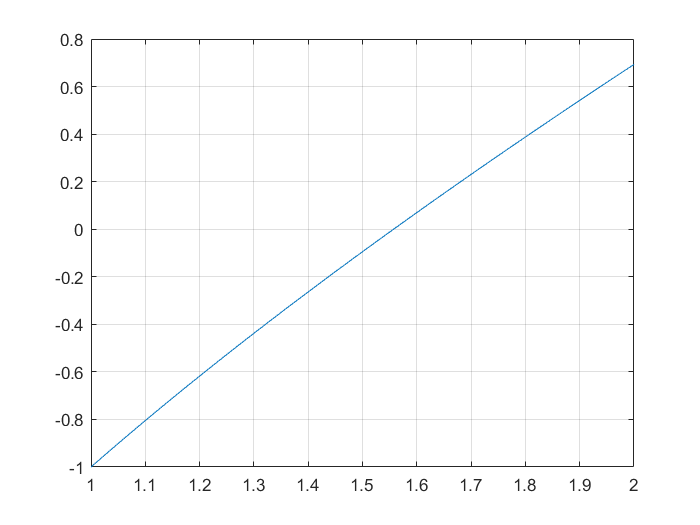

sample2 = 1:0.01:2;
plot(sample2, f_4_2(sample2))
grid on

由图解法可以得到根在区间$(1,2)$内，取1.5为牛顿-拉夫森方法的初始估计值，

$x_0=1.5,x_1=1.6$为割线法的两个初值。

[x_4_2_Netwon, flag_4_2_Netwon] = Netwon(f_4_2, df_4_2, 1.5, 1e-5, 10000, 2, 1)

Newton's method:
the root of f(x)=0 is x = 1.557146, the number of iterations is 3

x_4_2_Netwon =    1.557145598997611


flag_4_2_Netwon =      3


[x_4_2_Netwon_without_df, flag_4_2_Netwon_without_df] = Netwon_without_df(f_4_2, 1.5, 1e-5, 10000, 2, 1)

Newton's method without df:
the root of f(x)=0 is x = 1.557146, the number of iterations is 3

x_4_2_Netwon_without_df =    1.557145598997611


flag_4_2_Netwon_without_df =      3


[x_4_2_secant, flag_4_2_secant] = secant(f_4_2, 1.5, 1.6, 1e-5, 10000)

secant method:
the root of f(x)=0 is x = 1.557146, the number of iterations is 3

x_4_2_secant =    1.557145599061281


flag_4_2_secant =      3


对题（2）$$\ln x+x-2=0$$，牛顿-拉夫森方法和割线法均得到近似解$x\approx1.55714$，而且两者均为3次迭代。

**5.  Halley方法是求解非线性方程的一个数值方法， 它采用的递推公式是**

    
$$$$
    x_{n+1}=x_{n}-\frac{2f(x_n)f^\prime(x_n)}{2(f^\prime(x_n))^2-f(x_n)f^{\prime\prime}(x_n)}
    $$$$


**(1) 编写程序实现Halley算法， 并求解**$$f(x)=5x^7+2x-1$$**和**$$g(x)=1/x^3-10$
$**.**

**(2) 请根据你的结果判断Halley方法的收敛速度是否比牛顿方法更快？ Halley方法是线性收敛， 二次收敛，还是三次收敛？**

解：

(1)求解$$f(x)=5x^7+2x-1$$，易得$f'(x)=35x^6+2$，$f''(x)=210x^5$

f_5_1 = @(x)(5*x.^7 + 2*x - 1)

f_5_1 = 包含以下值的 function_handle :
    @(x)(5*x.^7+2*x-1)


df_5_1 = @(x)(35*x^6+2)

df_5_1 = 包含以下值的 function_handle :
    @(x)(35*x^6+2)


ddf_5_1 = @(x)(210*x^5)

ddf_5_1 = 包含以下值的 function_handle :
    @(x)(210*x^5)


sample5_1 = 0:0.01:1

sample5_1 =                    0   0.010000000000000   0.020000000000000   0.030000000000000   0.040000000000000   0.050000000000000   0.060000000000000   0.070000000000000   0.080000000000000   0.090000000000000   0.100000000000000   0.110000000000000   0.120000000000000   0.130000000000000   0.140000000000000   0.150000000000000   0.160000000000000   0.170000000000000   0.180000000000000   0.190000000000000   0.200000000000000   0.210000000000000   0.220000000000000   0.230000000000000   0.240000000000000   0.250000000000000   0.260000000000000   0.270000000000000   0.280000000000000   0.290000000000000   0.300000000000000   0.310000000000000   0.320000000000000   0.330000000000000   0.340000000000000   0.350000000000000   0.360000000000000   0.370000000000000   0.380000000000000   0.390000000000000   0.400000000000000   0.410000000000000   0.420000000000000   0.430000000000000   0.440000000000000   0.450000000000000   0.460000000000000   0.470000000000000   0.480000000000000   0.490

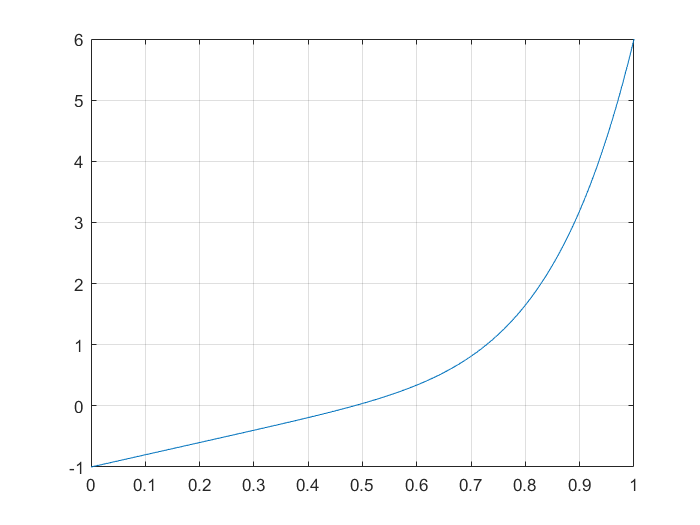

plot(sample5_1, f_5_1(sample5_1))
grid on

由图解法可以得到根在区间$(0,1)$内，取0.4为Halley算法和牛顿-拉夫森法的初始迭代点，$(0,1)$为二分法上下界。

[x_5_1_Netwon, flag_5_1_Netwon] = Netwon(f_5_1, df_5_1, 0.4, 1e-5, 10000, 1, 0)

Newton's method:
the root of f(x)=0 is x = 0.484363, the number of iterations is 4

x_5_1_Netwon =    0.484363490583416


flag_5_1_Netwon =      4


[x_5_1_Halley, flag_5_1_Halley] = Halley(f_5_1, df_5_1, ddf_5_1, 0.4, 1e-5, 10000, 1, 0)

Halley method:
the root of f(x)=0 is x = 0.484363, the number of iterations is 3

x_5_1_Halley =    0.484363490583416


flag_5_1_Halley =      3


[x_5_1_Halley_without_df_ddf, flag_5_1_Halley_without_df_ddf] = Halley_without_df_ddf(f_5_1, 0.4, 1e-5, 10000, 1, 0)

Halley method without df and ddf:
the root of f(x)=0 is x = 0.484363, the number of iterations is 3

x_5_1_Halley_without_df_ddf =    0.484363490583416


flag_5_1_Halley_without_df_ddf =      3


对$$5x^7+2x-1=0$$，Halley算法和牛顿-拉夫森方法均得到近似解$x\approx 0.48436$，Halley算法为3次迭代，牛顿-拉夫森方法为4次迭代。

求解$$g(x)=1/x^3-10$
$，易得$g'(x)=-\frac{3}{x^4}$，$g''(x)=\frac{12}{x^5}$

f_5_2 = @(x)(ones(size(x))./(x.^3) - 10)

f_5_2 = 包含以下值的 function_handle :
    @(x)(ones(size(x))./(x.^3)-10)


df_5_2 = @(x)(-3*ones(size(x))./(x.^4))

df_5_2 = 包含以下值的 function_handle :
    @(x)(-3*ones(size(x))./(x.^4))


ddf_5_2 = @(x)(12*ones(size(x))./(x.^5))

ddf_5_2 = 包含以下值的 function_handle :
    @(x)(12*ones(size(x))./(x.^5))


sample5_2 = 0.4:0.01:1

sample5_2 =    0.400000000000000   0.410000000000000   0.420000000000000   0.430000000000000   0.440000000000000   0.450000000000000   0.460000000000000   0.470000000000000   0.480000000000000   0.490000000000000   0.500000000000000   0.510000000000000   0.520000000000000   0.530000000000000   0.540000000000000   0.550000000000000   0.560000000000000   0.570000000000000   0.580000000000000   0.590000000000000   0.600000000000000   0.610000000000000   0.620000000000000   0.630000000000000   0.640000000000000   0.650000000000000   0.660000000000000   0.670000000000000   0.680000000000000   0.690000000000000   0.700000000000000   0.710000000000000   0.720000000000000   0.730000000000000   0.740000000000000   0.750000000000000   0.760000000000000   0.770000000000000   0.780000000000000   0.790000000000000   0.800000000000000   0.810000000000000   0.820000000000000   0.830000000000000   0.840000000000000   0.850000000000000   0.860000000000000   0.870000000000000   0.880000000000000   0.890

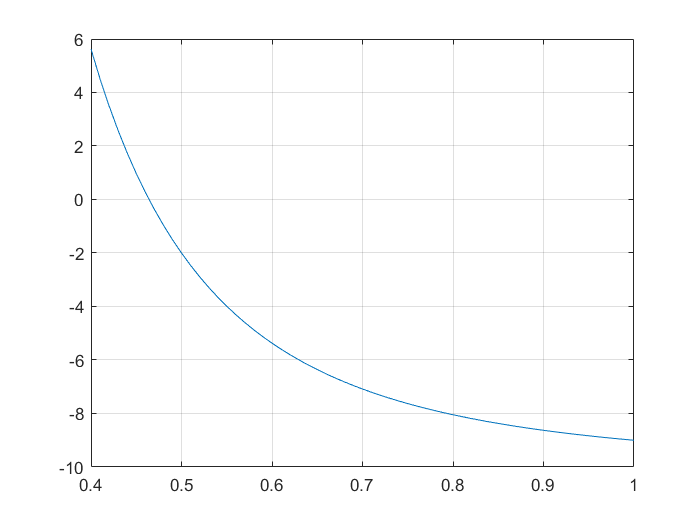

plot(sample5_2, f_5_2(sample5_2))
grid on

由图解法可以得到根在区间$(0.4,0.5)$内，取0.4为Halley算法和牛顿-拉夫森法的初始迭代点，$(0.4,0.5)$为二分法上下界。

[x_5_2_Netwon, flag_5_2_Netwon] = Netwon(f_5_2, df_5_2, 0.4, 1e-5, 10000, 0.5, 0.4)

Newton's method:
the root of f(x)=0 is x = 0.464159, the number of iterations is 4

x_5_2_Netwon =    0.464158883244858


flag_5_2_Netwon =      4


[x_5_2_Halley, flag_5_2_Halley] = Halley(f_5_2, df_5_2, ddf_5_2, 0.4, 1e-5, 10000, 0.5, 0.4)

Halley method:
the root of f(x)=0 is x = 0.464159, the number of iterations is 3

x_5_2_Halley =    0.464158883361278


flag_5_2_Halley =      3


[x_5_2_Halley_without_df_ddf, flag_5_2_Halley_without_df_ddf] = Halley_without_df_ddf(f_5_2, 0.4, 1e-5, 10000, 0.5, 0.4)

Halley method without df and ddf:
the root of f(x)=0 is x = 0.464159, the number of iterations is 3

x_5_2_Halley_without_df_ddf =    0.464158883361278


flag_5_2_Halley_without_df_ddf =      3


对$$1/x^3-10=0$
$，Halley算法和牛顿-拉夫森法均得到近似解$x\approx0.46415$，Halley算法为3次迭代，牛顿-拉夫森方法为4次迭代。

(2)根据结果明显Halley方法的收敛速度比牛顿方法更快，事实上牛顿方法为二次收敛，而Halley方法是三次收敛。


$$proof:\\
x_r-the\ real\ result\ of\ f(x)=0,\ we\ have\ x_{n+1}=x_n-\frac{2f(x_n)f^\prime(x_n)}{2(f^\prime(x_n))^2-f(x_n)f^{\prime\prime}(x_n)}\ ——(1)\\
Expand\ f(x_r)\ Taylor\ to\ the\ quadratic\ term\ at\ x_n:\\
f(x_r)\approx f(x_n)+f'(x_n)(x_r-x_n)+\frac{f''(x_n)}{2!}(x_r-x_n)^2=0\ ——(2)\\
from(1)\ we\ have\ (x_n-x_{n+1})\left[2(f'(x_n))^2-f(x_n)f''(x_n)\right]=2f(x_n)f'(x_n)\ ——(3)\\
from(2)\ we\ have\ 2f(x_n)f'(x_n)+2(f'(x_n))^2(x_r-x_n)+f''(x_n)f'(x_n)(x_r-x_n)^2=0\\
and\ f'(x_n)(x_r-x_n)=-f(x_n)-\frac{f''(x_n)}{2!}(x_r-x_n)^2\\
\Rightarrow\ 2f(x_n)f'(x_n)+\left[2(f'(x_n))^2-f''(x_n)f(x_n)\right](x_r-x_n)-\frac{(f''(x_n))^2}{2}(x_r-x_n)^3=0\ ——(4)\\
from(3)\ and\ (4)\ we\ have\ \left[2(f'(x_n))^2-f''(x_n)f(x_n)\right](x_r-x_{n+1})-\frac{(f''(x_n))^2}{2}(x_r-x_n)^3=0\\
actually,\ x_r-x_{n+1}=E_{n+1},\ x_r-x_n=E_n\\
\therefore E_{n+1}=\frac{(f''(x_n))^2}{2\left[2(f'(x_n))^2-f''(x_n)f(x_n)\right]}E_n^3\\
end\ proof.
$$


**6. 已知一个小球做斜抛运动， 它的运动轨道由下式给出**


$$   $$
   y=(\tan\theta_0)x -\frac{g}{2v_0^2\cos^2\theta_0}x^2+y_0
   $$$$


**   若初始速率**$$v_0=30$ $**m/s, 发球处的高度为1.8m, 接球处的高度为1m。 求投射的初始角度**$$\theta_0$$**, 使得发球处和接球处的水平距离为90m. **$$g=9.81$ $**m/s**$$^2$$**.**

解：

将题目中变量代入得方程$1=(tan\theta_0)\times90-\frac{9.81}{2\times30^2cos^2\theta_0}\times90^2+1.8$，其中$\theta_0$为弧度制。

化简后求$f(\theta_0)=90(tan\theta_0)-\frac{9.81\times90^2}{2\times30^2cos^2\theta_0}+0.8$的零点。

sample_6 = pi/8:pi/128:(pi/2-pi/8)

sample_6 =    0.392699081698724   0.417242774304894   0.441786466911065   0.466330159517235   0.490873852123405   0.515417544729575   0.539961237335746   0.564504929941916   0.589048622548086   0.613592315154256   0.638136007760427   0.662679700366597   0.687223392972767   0.711767085578938   0.736310778185108   0.760854470791278   0.785398163397448   0.809941856003619   0.834485548609789   0.859029241215959   0.883572933822129   0.908116626428300   0.932660319034470   0.957204011640640   0.981747704246810   1.006291396852981   1.030835089459151   1.055378782065321   1.079922474671491   1.104466167277662   1.129009859883832   1.153553552490002   1.178097245096172


f_6 = @(x)(90*tan(x)-9.81*90^2*ones(size(x))./(2*30^2*(cos(x)).^2))+0.8

f_6 = 包含以下值的 function_handle :
    @(x)(90*tan(x)-9.81*90^2*ones(size(x))./(2*30^2*(cos(x)).^2))+0.8


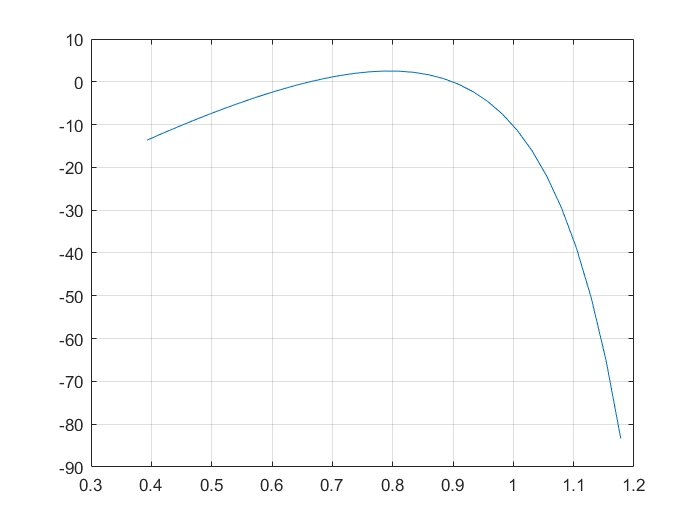

plot(sample_6, f_6(sample_6))
grid on

理论上$\theta_0\in[0,\frac{\pi}2]$，由图解法可以得到根在$(0.6, 0.7)$和$(0.8,1)$的区间内，由于方程难以化为$x=g(x)$，而且导数较为复杂，故使用割线法求解，选取$x_0=0.6,x_1=0.7$为第一个根的初值、$x_0=0.8,x_1=1.0$为第二个根的初值。

[x_6_1, ~] = secant(f_6, 0.6, 0.7, 1e-5, 10000)

secant method:
the root of f(x)=0 is x = 0.662509, the number of iterations is 4

x_6_1 =    0.662509230665580


x_6_1_check = fzero(f_6, [0.6, 0.7])

x_6_1_check =    0.662509214398280


e_r_6_1 = relative_e(x_6_1, x_6_1_check)

相对误差为: 2.455407e-08

e_r_6_1 =      2.455407401293869e-08


[x_6_2, ~] = secant(f_6, 0.8, 1.0, 1e-5, 10000)

secant method:
the root of f(x)=0 is x = 0.899398, the number of iterations is 8

x_6_2 =    0.899398457591826


x_6_2_check = fzero(f_6, [0.8, 1.0])

x_6_2_check =    0.899398457607284


e_r_6_2 = relative_e(x_6_2, x_6_2_check)

相对误差为: -1.718676e-11

e_r_6_2 =     -1.718676084377725e-11


theta_0_1 = rad2deg(x_6_1)

theta_0_1 =   37.958982805596868


theta_0_2 = rad2deg(x_6_2)

theta_0_2 =   51.531735720587577


由割线法求解得到$\theta_0\approx0.66251=37.959^\circ$或$\theta_0 \approx0.89939=51.531^\circ$。（并通过fzero函数进行验证正确），即当投射的初始角度为$37.959^\circ$或$51.531^\circ$时，发球处和接球处的水平距离为90m。

**7. 一个质量为**$$m$$**的物块从高处**$$h$$**静止释放后落到一个非线性弹簧上， 使得弹簧收缩**$$d$$**, 此时物块所受的恢复力为**


$$   $$
   F=-(k_1d + k_2d^{3/2})
   $$$$


**   忽略空气阻力等因素， 可以证明下式满足**


$$   $$
   0=\frac{2k_2d^{5/2}}{5}+\frac{1}{2}k_1d^2-mgd-mgh
   $$$$


**   若已知这些参数**$$k_1=40,000 g/s^2, k_2=40 g/(s^2m^{1/2}), m=95 g, g=9.81m/s^2, h=0.43 m$$**, 求**$$d$$**.**

解：

将参数代入方程得$\frac{2\times40d^{5/2}}{5}+\frac12 \times40000d^2-95\times9.81d-95\times9.81\times0.43=0$，

令$f(x)=\frac{2\times40d^{5/2}}{5}+\frac12 \times40000d^2-95\times9.81d-95\times9.81\times0.43$，求其零点。

sample_7 = 0:0.001:0.2

sample_7 =                    0   0.001000000000000   0.002000000000000   0.003000000000000   0.004000000000000   0.005000000000000   0.006000000000000   0.007000000000000   0.008000000000000   0.009000000000000   0.010000000000000   0.011000000000000   0.012000000000000   0.013000000000000   0.014000000000000   0.015000000000000   0.016000000000000   0.017000000000000   0.018000000000000   0.019000000000000   0.020000000000000   0.021000000000000   0.022000000000000   0.023000000000000   0.024000000000000   0.025000000000000   0.026000000000000   0.027000000000000   0.028000000000000   0.029000000000000   0.030000000000000   0.031000000000000   0.032000000000000   0.033000000000000   0.034000000000000   0.035000000000000   0.036000000000000   0.037000000000000   0.038000000000000   0.039000000000000   0.040000000000000   0.041000000000000   0.042000000000000   0.043000000000000   0.044000000000000   0.045000000000000   0.046000000000000   0.047000000000000   0.048000000000000   0.0490

f_7 = @(x)(2*40*x.^(2.5)./5 + 0.5*40000*x.^2 - 95*9.81*x - 95*9.81*0.43)

f_7 = 包含以下值的 function_handle :
    @(x)(2*40*x.^(2.5)./5+0.5*40000*x.^2-95*9.81*x-95*9.81*0.43)


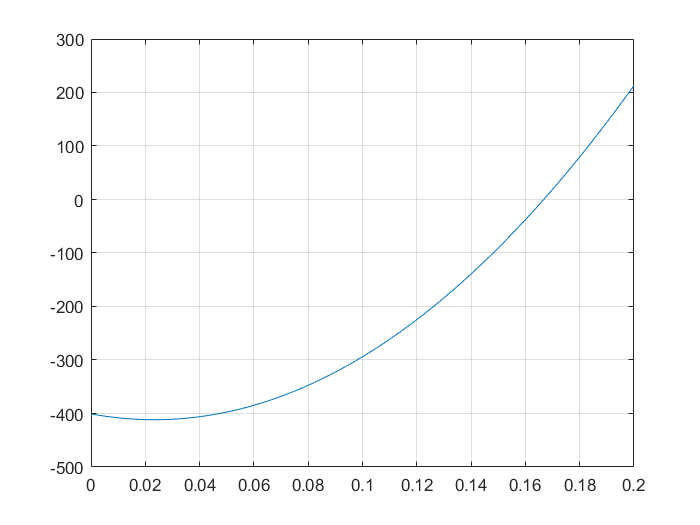

plot(sample_7, f_7(sample_7))
grid on

由图解法可以得到根在$(0,0.2)$的区间内，使用牛顿-拉夫森方法，其中$f'(x)=40d^{3/2}+40000d-95\times9.81$，初始估计值为0.16，$(0,0.2)$为二分法区间。

[x_7, ~] = Netwon_without_df(f_7, 0.16, 1e-5, 10000, 0.2, 0)

Newton's method without df:
the root of f(x)=0 is x = 0.166724, the number of iterations is 3

x_7 =    0.166723562437816


x_7_check = fzero(f_7, [0.2, 0])

x_7_check =    0.166723562437785


e_r_7 = relative_e(x_7, x_7_check)

相对误差为: 1.896169e-13

e_r_7 =      1.896168733678443e-13


由牛顿-拉夫森方法得到近似解$d\approx0.16672$m。（并通过fzero函数进行验证正确）

**8. 一根质量均匀分布的缆线两端固定被悬挂起来，通过受力分析， 发现缆线的高度**$$y$$**与水平位置**$$x$$**的关系由下式决定**


$$   $$
   y = \frac{T_A}{w}\cosh\left(\frac{w}{T_A}x\right)+y_0-\frac{T_A}{w}
   $$$$


**   其中**$$T_A$$**是**$$x=0$$**处的张力，**$ $w$$**是缆线单位长度的重量。**

**   (1) 若**$$w=10$$** N/m, **$$y_0$$**=5 m, 并且**$$x=50$**m处， **$$y=15$ $**m, 求**$$T_A$$**.**

**   (2) 请在区间**$$[-50,100]$$**上绘制**$$y(x)$$**曲线。**

解：

（1）将参数代入方程得$15=\frac {T_A}{10}cosh(\frac{10}{T_A}\times50)+5-\frac{T_A}{10}$，

令$f(x)=\frac {T_A}{10}cosh(\frac{10}{T_A}\times50)-10-\frac{T_A}{10}$，求其零点。

sample_8_1 = 1200:1:1300;
f_8 = @(x)(x./10.*cosh(10*50*ones(size(x))./x)- 10 - x./10)

f_8 = 包含以下值的 function_handle :
    @(x)(x./10.*cosh(10*50*ones(size(x))./x)-10-x./10)


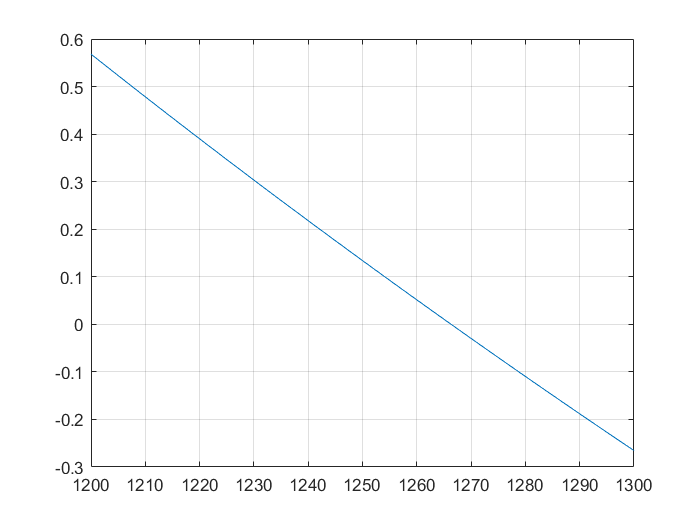

plot(sample_8_1, f_8(sample_8_1))
grid on

由图解法可以得到根在$(1200,1300)$的区间内，使用割线法选取$x_0=1260,x_1=1270$为初值。

T_A = secant(f_8, 1260, 1270, 1e-5, 10000)

secant method:
the root of f(x)=0 is x = 1266.324360, the number of iterations is 4

T_A =      1.266324360399889e+03


T_A_check = fzero(f_8, [1260, 1270])

T_A_check =      1.266324360399887e+03


e_r_8 = relative_e(T_A, T_A_check)

相对误差为: 1.615987e-15

e_r_8 =      1.615986506287281e-15


使用割线法得到近似解$T_A\approx1266.32436$N。（并通过fzero函数进行验证正确）

（2）将$T_A$代入$y(x)$得$y(x)=\frac{1266.32436}{10}cosh(\frac{10x}{1266.32436})+5-\frac{1266.32436}{10}$

sample_8_2 = -50:100

sample_8_2 =    -50   -49   -48   -47   -46   -45   -44   -43   -42   -41   -40   -39   -38   -37   -36   -35   -34   -33   -32   -31   -30   -29   -28   -27   -26   -25   -24   -23   -22   -21   -20   -19   -18   -17   -16   -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1


y = @(x)(1266.32436/10*cosh(10*x/1266.32436) + 5 - 1266.32436/10)

y = 包含以下值的 function_handle :
    @(x)(1266.32436/10*cosh(10*x/1266.32436)+5-1266.32436/10)


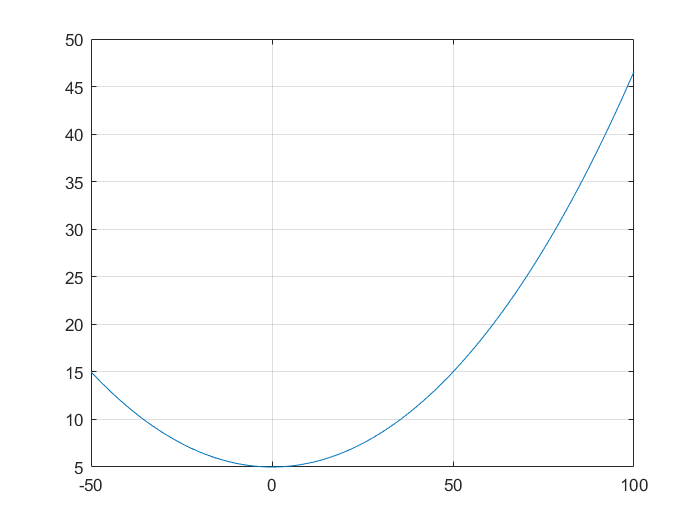

plot(sample_8_2, y(sample_8_2))
grid on

$y(x)$在区间$[-50,100]$的曲线如图所示。

**********************************************functions******************************************************

dichotomy：二分法


$$mid=(high + low)/2$$


args：

    f：寻根的函数

    a：区间上界

    b：区间下界

    epsilon：误差范围

output:

    当$flag=-2$，表示初始区间不存在根，$answer=NaN$；

    其他情况下，$flag$表示迭代次数，$answer$为寻得的根。

function [answer, flag] = dichotomy(f, a, b, epsilon)
    fprintf('dichotomy:\n');
    high = a;
    low = b;
    count = 0;
    if(f(high)*f(low) > 0)
        fprintf('此区间不存在根!');
    elseif(f(high) == 0)
        answer = high;
        fprintf('the root of f(x)=0 is x = %f', answer);
    elseif(f(low) == 0)
        answer = low;
        fprintf('the root of f(x)=0 is x = %f', answer);
    else
        mid = (high + low) / 2;
        while(f(mid) ~= 0 && (high - low) > 2*epsilon)
            count = count + 1;
            if(f(high)*f(mid) < 0)
                low = mid;
            else
                high = mid;
            end
            mid = (high + low) / 2;
        end
    end
    switch count
        case 0
            flag = -2; answer = NaN;
        otherwise
            flag = count; answer = mid;
            fprintf('the root of f(x)=0 is x = %f, the number of iterations is %d', answer, count);
    end
end

fixedPoint：定点迭代法


$$x_{n+1}=g(x_n)$$


args：

    g：寻根的函数

    x0：初始估计值

    epsilon：误差上限

    max_n：最多迭代次数（防止发散）

output:

    当$flag=-1$，表示可能不收敛或最多迭代次数不足以达到精度，$answer=NaN$；

    其他情况下，$flag$表示迭代次数，$answer$为寻得的根。

function [answer, flag] = fixedPoint(g, x0, epsilon, max_n)
    fprintf('fixedPoint:\n');
    count = 0;
    fPoint = x0;
    
    while(count < max_n && abs(fPoint - g(fPoint)) > epsilon)
        fPoint = g(fPoint);
        count = count + 1;
    end
    
    if(count == max_n)
        flag = -1; answer = NaN;
        fprintf('it may not converge or the iterations are not enough!')
    else
        flag = count; answer = fPoint;
        fprintf('the root of g(x)=x is x = %f, the number of iterations is %d', answer, count);
    end
end

fixedPointWithAitken：使用Aitken加速方法的定点迭代方法


$$Algorithm-Aitken's\ Method\\
Choose\ initial\ approximation\ x_0\\
Do\\
\quad Calculate\ x_{3i+1}\ and\ x_{3i+2}\ from\ x_{3i}\ using\ any\ linear\ iterative\ method\\
\quad Modify\ x_{3i+3}\ using\\
\quad x_{3i+3}=x_{3i+2}-\frac{(x_{3i+2}-x_{3i+1})^2}{x_{3i}-2x_{3i+1}+x_{2i+2}}\quad i=0, 1,2,\dots\\
while(none\ of\ the\ convergence\ criterion\ is\ met)$$


args：

    g：寻根的函数

    x0：初始估计值

    epsilon：误差上限

    max_n：最多迭代次数（防止发散）

output:

    当$flag=-1$，表示可能不收敛或最多迭代次数不足以达到精度，$answer=NaN$；

    其他情况下，$flag$表示迭代次数，$answer$为寻得的根。

function [answer, flag] = fixedPointWithAitken(g, x0, epsilon, max_n)
    fprintf('fixedPoint with Aitken:\n');
    count = 0;
    fPoint0 = x0;
    while(count < max_n && abs(fPoint0 - g(fPoint0)) > epsilon)
        fPoint1 = g(fPoint0);
        fPoint2 = g(fPoint1);
        fPoint0 = fPoint2 - (fPoint2 - fPoint1)^2/(fPoint0 - 2*fPoint1 + fPoint2); 
        count = count + 3;
    end
    
    if(count == max_n)
        flag = -1; answer = NaN;
        fprintf('it may not converge or the iterations are not enough!')
    else
        flag = count; answer = fPoint0;
        fprintf('the root of g(x)=x is x = %f, the number of iterations is %d', answer, count);
    end
end

Netwon：使用牛顿-拉夫森方法，需要将导数以参数形式传入，并用二分法区间修正发散解


$$x_{n+1}=x_{n}-\frac{f(x_n)}{f'(x_n)}$$


args：

    f：寻根的函数

    df：寻根函数的导数

    x0：初始估计值$x_0$

    epslion：误差上限

    max_n：最多计算步数

    high：二分法区间上限

    low：二分法区间下限

output:

    当$flag=-1$，表示可能不收敛或最多迭代次数不足以达到精度，$answer=NaN$；

    当$flag=-2$，表示初始区间不存在根，$answer=NaN$；

    其他情况下，$flag$表示迭代次数，$answer$为寻得的根。

function [answer, flag] = Netwon(f, df, x0, epsilon, max_n, high, low)
    fprintf('Newton''s method:\n');
    count = 0;
    initialP = x0;
    if(f(high)*f(low) > 0)
        fprintf('二分法区间不存在根！');
        
    else
        % 假如初始估计值在二分法区间外，则用(high + low) / 2代替
        if(x0 > high || x0 < low)
            initialP = (high + low) / 2;
        end
        while(count < max_n)
            count = count + 1;
            tmp = initialP; %判断是否停
            initialP = initialP - f(initialP)/df(initialP);
            %如果迭代结果在二分范围外则换为(high + low)/2，并根据迭代结果更新high和low
            if(initialP > high || initialP < low)
                initialP = (high + low) / 2;
            end
            if(f(high)*f(initialP) < 0)
                low = initialP;
            else
                high = initialP;
            end
            if(abs(tmp - initialP) < epsilon)
                break;
            end
        end
    end
    switch count
        case max_n
            flag = -1; answer = NaN;
            fprintf('it may not converge or the iterations are not enough!')
        case 0
            flag = -2; answer = NaN;
        otherwise
            flag = count; answer = initialP;
            fprintf('the root of f(x)=0 is x = %f, the number of iterations is %d', answer, count);
    end
end

Netwon_without_df：使用牛顿-拉夫森方法，不需要将导数以参数形式传入，并用二分法区间修正发散解（author：鲁潇阳）


$$x_{n+1}=x_{n}-\frac{f(x_n)}{f'(x_n)}$$


args：

    f：寻根的函数

    x0：初始估计值$x_0$

    epslion：误差上限

    max_n：最多计算步数

    high：二分法区间上限

    low：二分法区间下限

output:

    当$flag=-1$，表示可能不收敛或最多迭代次数不足以达到精度，$answer=NaN$；

    当$flag=-2$，表示初始区间不存在根，$answer=NaN$；

    其他情况下，$flag$表示迭代次数，$answer$为寻得的根。

function [answer, flag] = Netwon_without_df(f, x0, epsilon, max_n, high, low)
    fprintf('Newton''s method without df:\n');
    % 计算一阶导数
    syms x;
    fun = f(x);
    df = matlabFunction(diff(fun)); % 通过符号函数求导，并转换为可计算的函数
    % 求根
    count = 0;
    initialP = x0;
    if(f(high)*f(low) > 0)
        fprintf('二分法区间不存在根！');
        
    else
        % 假如初始估计值在二分法区间外，则用(high + low) / 2代替
        if(x0 > high || x0 < low)
            initialP = (high + low) / 2;
        end
        while(count < max_n)
            count = count + 1;
            tmp = initialP; % 保存前一次计算值，用于判断是否停
            initialP = initialP - f(initialP)/df(initialP);
            
            % 如果迭代结果在二分范围外则换为(high + low)/2，并根据迭代结果更新high和low
            if(initialP > high || initialP < low)
                initialP = (high + low) / 2;
            end
            if(f(high)*f(initialP) < 0)
                low = initialP;
            else
                high = initialP;
            end
            if(abs(tmp - initialP) < epsilon)
                break;
            end
        end
    end
    switch count
        case max_n
            flag = -1; answer = NaN;
            fprintf('it may not converge or the iterations are not enough!')
        case 0
            flag = -2; answer = NaN;
        otherwise
            flag = count; answer = initialP;
            fprintf('the root of f(x)=0 is x = %f, the number of iterations is %d', answer, count);
    end
end

secant：割线法


$$x_{n+1}=x_n-\frac{x_n-x_{n-1}}{f(x_n)-f(x_{n-1})}f(x_n)$$


args：

    f：寻根的函数

    x0：初值$x_0$

    x1：初值$x_1$

    epsilon：误差上限

    max_n：最多计算次数

output:

    当$flag=-1$，表示可能不收敛或最多迭代次数不足以达到精度，$answer=NaN$；

    其他情况下，$flag$表示迭代次数，$answer$为寻得的根。

function [answer, flag] = secant(f, x0, x1, epsilon, max_n)
    fprintf('secant method:\n');
    count = 0;
    p1 = x0;
    p2 = x1;
    while(count < max_n && abs(p1 - p2) > epsilon)
        count = count + 1;
        %临时存放p2，作为下次迭代的p1
        tmp = p2;
        p2 = p2 - f(p2)*(p2 - p1)/(f(p2) - f(p1));
        p1 = tmp;
    end
    
    if(count == max_n)
        flag = -1; answer = NaN;
        fprintf('it may not converge or the iterations are not enough!')
    else
        flag = count; answer = p2;
        fprintf('the root of f(x)=0 is x = %f, the number of iterations is %d', answer, count);
    end
end

Halley：Halley方法，需要将函数的一阶和二阶导数以参数形式传入，并使用二分法区间修正发散解

args：

    f：寻根的函数

    df：寻根函数的一阶导数

    ddf：寻根函数的二阶导数

    x0：初始的估计值

    epsilon：误差上限

    max_n：最多计算的次数

    high：二分法区间上限

    low：二分法区间下限

output:

    当$flag=-1$，表示可能不收敛或最多迭代次数不足以达到精度，$answer=NaN$；

    当$flag=-2$，表示初始区间不存在根，$answer=NaN$；

    其他情况下，$flag$表示迭代次数，$answer$为寻得的根。

function [answer, flag] = Halley(f, df, ddf, x0, epsilon, max_n, high, low)
    fprintf('Halley method:\n');
    count = 0;
    initialP = x0;
    if(f(high)*f(low) > 0)
        fprintf('二分法区间不存在根！');
        
    else
        % 假如初始估计值在二分法区间外，则用(high + low) / 2代替
        if(x0 > high || x0 < low)
            initialP = (high + low) / 2;
        end
        while(count < max_n)
            count = count + 1;
            tmp = initialP;
            initialP = initialP - 2*f(initialP)*df(initialP)/(2*(df(initialP))^2-f(initialP)*ddf(initialP));
            %如果迭代结果在二分范围外则换为(high + low)/2，并根据迭代结果更新high和low
            if(initialP > high || initialP < low)
                initialP = (high + low) / 2;
            end
            if(f(high)*f(initialP) < 0)
                low = initialP;
            else
                high = initialP;
            end
            if(abs(tmp - initialP) < epsilon)
                break;
            end
        end
    end
    switch count
        case max_n
            flag = -1; answer = NaN;
            fprintf('it may not converge or the iterations are not enough!')
        case 0
            flag = -2; answer = NaN;
        otherwise
            flag = count; answer = initialP;
            fprintf('the root of f(x)=0 is x = %f, the number of iterations is %d', answer, count);
    end
end

Halley_without_df_ddf：Halley方法，不需要将函数的一阶和二阶导数以参数形式传入，并使用二分法区间修正发散解（author：鲁潇阳）

args：

    f：寻根的函数

    x0：初始的估计值

    epsilon：误差上限

    max_n：最多计算的次数

    high：二分法区间上限

    low：二分法区间下限

output:

    当$flag=-1$，表示可能不收敛或最多迭代次数不足以达到精度，$answer=NaN$；

    当$flag=-2$，表示初始区间不存在根，$answer=NaN$；

    其他情况下，$flag$表示迭代次数，$answer$为寻得的根。

function [answer, flag] = Halley_without_df_ddf(f, x0, epsilon, max_n, high, low)
    fprintf('Halley method without df and ddf:\n');
    % 计算一阶和二阶导数
    syms x;
    fun = f(x);
    df = matlabFunction(diff(fun, x, 1)); % 通过符号函数求导，并转换为可计算的函数
    ddf = matlabFunction(diff(fun, x, 2));
    % 求根
    count = 0;
    initialP = x0;
    if(f(high)*f(low) > 0)
        fprintf('二分法区间不存在根！');
    
    else
        % 假如初始估计值在二分法区间外，则用(high + low) / 2代替
        if(x0 > high || x0 < low)
            initialP = (high + low) / 2;
        end
        while(count < max_n)
            count = count + 1;
            tmp = initialP;
            initialP = initialP - 2*f(initialP)*df(initialP)/(2*(df(initialP))^2-f(initialP)*ddf(initialP));
            % 如果迭代结果在二分范围外则换为(high + low)/2，并根据迭代结果更新high和low
            if(initialP > high || initialP < low)
                initialP = (high + low) / 2;
            end
            if(f(high)*f(initialP) < 0)
                low = initialP;
            else
                high = initialP;
            end
            if(abs(tmp - initialP) < epsilon)
                break;
            end
        end
    end
    switch count
        case max_n
            flag = -1; answer = NaN;
            fprintf('it may not converge or the iterations are not enough!')
        case 0
            flag = -2; answer = NaN;
        otherwise
            flag = count; answer = initialP;
            fprintf('the root of f(x)=0 is x = %f, the number of iterations is %d', answer, count);
    end
end

计算相对误差的函数，并显示

args:

    x_approx：估计值

    x_real：真值

function output = relative_e(x_approx, x_real)
    output = (x_approx - x_real .* ones(size(x_approx)))./x_real;
    fprintf("相对误差为: %e" , output);
end